# Laboratorium 1

Janusz Pawlicki

## 1. Wstęp 

## 1.1 Układy LTI

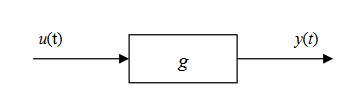

Powyższy układ będzie liniowy jeśli spełniona będzie zasada superpozycji:

oraz zasada jednorodności:

Powyższy układ będzie niezmienniczy w czasie jeśli na opóźnione wejście odpowie tak samo opóźnionym wyjściem, czyli spełniona będzie zasada:

W Matlabie istnieją cztery podstawowe sposoby reprezentacji układów liniowych, niezmienniczych w czasie (ang. *Linear Time-Invariant*, LTI):

• za pomocą transmitancji (ang.* transfer function*),

• za pomocą zer, biegunów i wzmocnienia układu (ang. *zero/pole/gain*),

• w przestrzeni stanów (ang. *state space*),

• w postaci schematu blokowego w Simulinku.

## 1.2 Transformata Laplace'a

Transformata Laplace’a funkcji f (t) – lokalnie całkowalnej – jest dana jako:

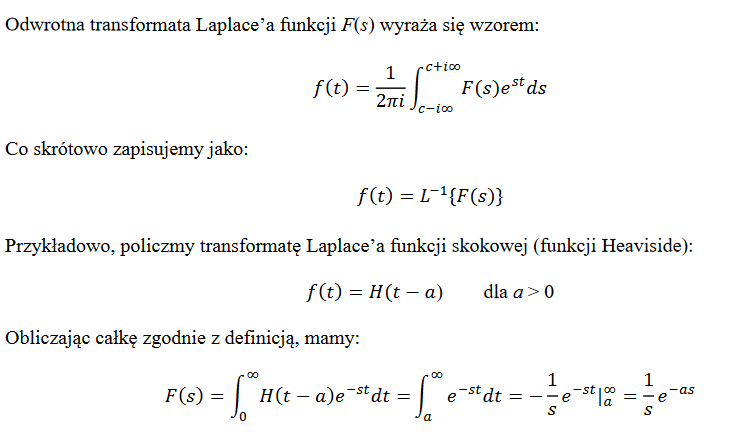

## 1.3 Transmitacja

Transmitancja operatorowa (funkcja przejścia) to stosunek transformaty Laplace'a sygnału wyjściowego Y(s) do transformaty Laplace'a sygnału wejściowego U(s) przy zerowych warunkach początkowych:

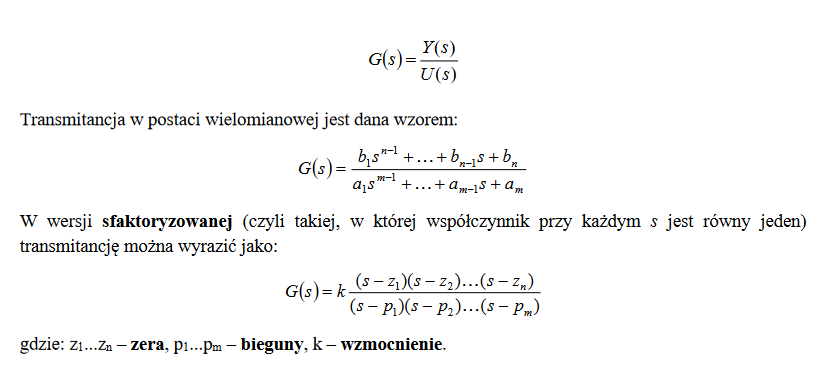

Uproszczony model zawieszenia samochodowego można przedstawić za pomocą układu inercyjnego II rzędu:

### 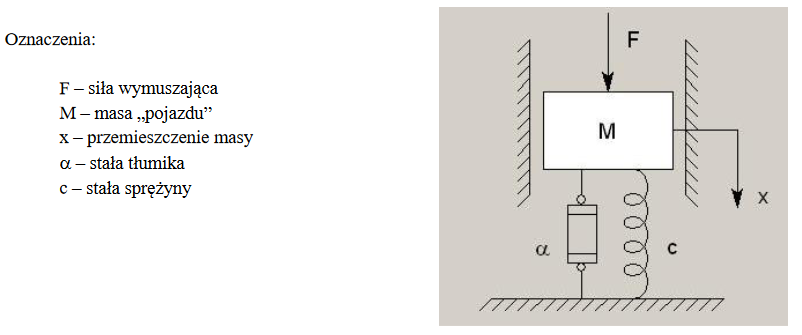

### 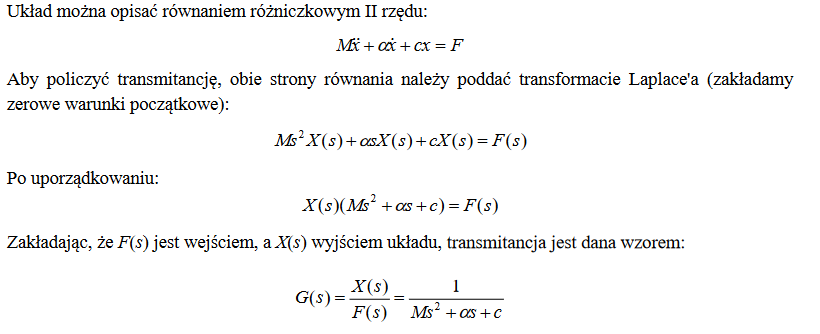

## 1.4 Przetrzeń stanów

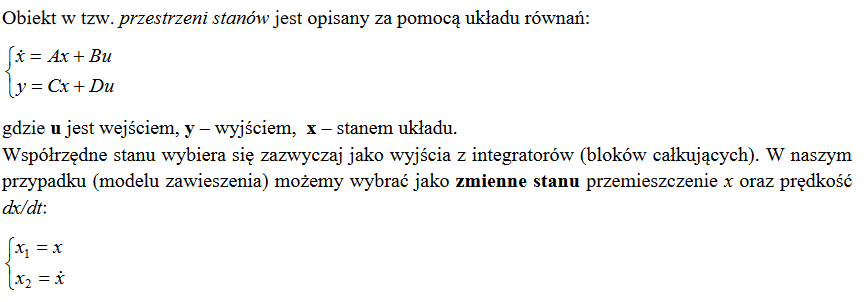

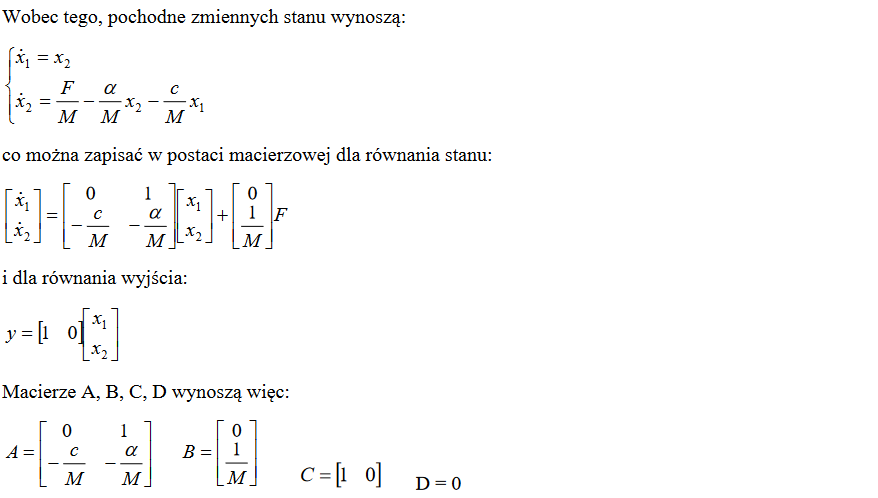

### Zadanie 1.

Narysuj funkcję Heaviside oraz jej transformatę Laplace’a dla a = 1 za pomocą funkcji `ezplot`

a) Definiiowanie zmiennych symbolicznych.

syms t s
syms a positive
f = heaviside(t - a)

$$f = \mathrm{heaviside}\left(t-a\right)$$

Fs = laplace(f, t, s)

$$Fs = \frac{{\mathrm{e}}^{-a\,s}}{s}$$

b) Rysowanie wykresów funkcji za pomocą funkcji ezplot.

a = 1

a = 1

f1 = heaviside(t - a)

$$f1 = \mathrm{heaviside}\left(t-1\right)$$

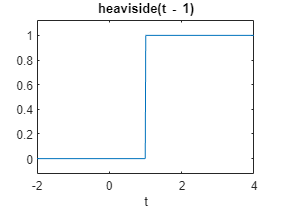

ezplot(f1, [-2, 4])

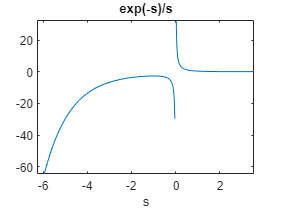

ezplot(laplace(f1, t, s))

### Zadanie 2.

M = 1000

M = 1000

F = 1000

F = 1000

alfa = 500

alfa = 500

c = 400

c = 400

licz = [0 0 1]

licz =      0     0     1


mian = [1000 500 400]

mian =         1000         500         400


a) Odpowiedz na pytania:

- czy bieguny są rzeczywiste?

- czy układ jest stabilny?

obiekt = tf(licz, mian)

obiekt =
 
            1
  ----------------------
  1000 s^2 + 500 s + 400
 
Continuous-time transfer function.



Pole = pole(obiekt)

Pole =   -0.2500 + 0.5809i
  -0.2500 - 0.5809i


stable = isstable(obiekt)

stable = logical
   1


Bieguny są zespolone.

Układ jest stabilny.

b) Za pomocą funkcji tf2zp oblicz zera, bieguny i wzmocnienie transmitancji i przedstaw ją w postaci sfaktoryzowanej.

[z, p, k] = tf2zp(licz, mian)


z =

  0×1 empty double column vector



p =   -0.2500 + 0.5809i
  -0.2500 - 0.5809i


k = 1.0000e-03

zeros = z


zeros =

  0×1 empty double column vector



bieguny = p

bieguny =   -0.2500 + 0.5809i
  -0.2500 - 0.5809i


wzmocnienie = k

wzmocnienie = 1.0000e-03

factor_form = tf([0 0 1/c], [M/c alfa/c 1])

factor_form =
 
         0.0025
  --------------------
  2.5 s^2 + 1.25 s + 1
 
Continuous-time transfer function.



c) Dobierz tak parametry układu aby zaobserwować odpowiedzi układu na skok jednostkowy w przypadku oscylacyjnym i tłumionym.

zeta = alfa/(2 * sqrt(c * M))

zeta = 0.3953

Dla wcześniej podanych parametrów układ jest oscylacyjny.

M1 = 500

M1 = 500

c1 = 200

c1 = 200

alfa1 = 650

alfa1 = 650

zeta1 = alfa1/(2 * sqrt(c1 * M1))

zeta1 = 1.0277

Dla nowo dobranych parametrów układ jest tłumiony.

### Zadanie 3.

Za pomocą funkcji zpk zapisz poniższą transmitancję:

Wpółczynniki funkcji zpk to :

- z = -1/4

- p = [0 -5 -1/10]

- k = 2

obiekt = zpk(-1/4, [0 -5 -1/10], 2)

obiekt =
 
    2 (s+0.25)
  ---------------
  s (s+5) (s+0.1)
 
Continuous-time zero/pole/gain model.



### Zadanie 4.

Dokonaj konwersji transmitancji modelu zawieszenia do przestrzeni stanów obiema metodami tj. za pomocą funkcji `zp2ss` oraz `tf2ss` i porównaj wyniki (czy macierze `A,B,C,D` są takie same? czy odpowiedzi skokowe są takie same?).

A = [ 0, 1; -c/M, -alfa/M]

A =          0    1.0000
   -0.4000   -0.5000


B = [0; 1/M]

B = 	1.0e+-3 *

         0
    1.0000


C = [1 0]

C =      1     0


D = 0

D = 0

obiekt = ss(A, B, C, D)

obiekt =
 
  A = 
         x1    x2
   x1     0     1
   x2  -0.4  -0.5
 
  B = 
          u1
   x1      0
   x2  0.001
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



a) Funkcja zp2ss

[A1, B1, C1, D1] = zp2ss(z, p, k)

A1 =    -0.5000   -0.6325
    0.6325         0


B1 =      1
     0


C1 =          0    0.0016


D1 = 0

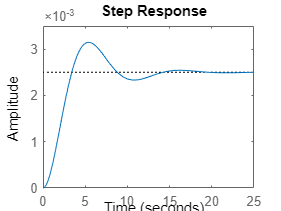

step(A1, B1, C1, D1)

b) Funkcja tf2ss

[A2, B2, C2, D2] = tf2ss(licz, mian)

A2 =    -0.5000   -0.4000
    1.0000         0


B2 =      1
     0


C2 = 	1.0e+-3 *

         0    1.0000


D2 = 0

step(A2, B2, C2, D2)

Macierze funkcji zp2ss i tf2ss nie są takie same.

 Natomiast odpowiedzi skokowe w postaci wykresu są takie same.

### Zadanie 5.

Oblicz transmitancję zastępczą Gsys dla połączenia szeregowego, równoległego i ujemnego sprzężenia

zwrotnego, zakładając, że transmitancje obiektów sys1 i sys2 są dane jako:

a) Gsys1

licz1 = [1 1]

licz1 =      1     1


mian1 = [1 5 1]

mian1 =      1     5     1


gsys1 = tf(licz1, mian1)

gsys1 =
 
      s + 1
  -------------
  s^2 + 5 s + 1
 
Continuous-time transfer function.



b) Gsys2

licz2 = [1]

licz2 = 1

mian2 = [1 1 -2 1]

mian2 =      1     1    -2     1


gsys2 = tf(licz2, mian2)

gsys2 =
 
           1
  -------------------
  s^3 + s^2 - 2 s + 1
 
Continuous-time transfer function.



transmitacja zastępcza dla połączenia szeregowego

sys_series = series(gsys1, gsys2)

sys_series =
 
                  s + 1
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 3 s + 1
 
Continuous-time transfer function.



transmitacja zastępcza dla połączenia równoległego

sys_parallel = parallel(gsys1, gsys2)

sys_parallel =
 
          s^4 + 2 s^3 + 4 s + 2
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 3 s + 1
 
Continuous-time transfer function.



transmitacja zastępcza dla ujemnego sprzężenia

sys_feedbck = feedback(gsys1, gsys2)

sys_feedbck =
 
        s^4 + 2 s^3 - s^2 - s + 1
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 4 s + 2
 
Continuous-time transfer function.

